% Folder in which all test data folders are located
addpath(genpath(fullfile(pwd,'sw')))
rcbench_folder = fullfile(fileparts(pwd),'Data','RC Testbench Data/RC Testbench Data');
% List of folders of the specific tests
test_folder = {'T-motor MN3510 360 kv - MF1302R - 6S'};

%% Get the data
for n = 1:length(test_folder)
    folder = fullfile(rcbench_folder, test_folder{n});
    data = RCTestbench.getData(folder);
%     data{n} = data{n}.getFOM;
end

Extract the data from the performance tests

pwm         = [data.perf.test1.pwm;data.perf.test2.pwm;data.perf.test3.pwm];
rpm         = [data.perf.test1.RPM;data.perf.test2.RPM;data.perf.test3.RPM];
T           =  [data.perf.test1.T;data.perf.test2.T;data.perf.test3.T];
Qm          =  [data.perf.test1.Qm;data.perf.test2.Qm;data.perf.test3.Qm];

Perform a fit with a quadratic

deg         = 2;
p_T      = polyfit(rpm,T,deg);
p_Qm     = polyfit(rpm,Qm,deg);
p_T_pwm  = polyfit(pwm,T,deg);
p_Qm_pwm = polyfit(pwm,Qm,deg);
[rmse_T,me_T] = rmse_maxerror(rpm,T,p_T);
[rmse_Qm,me_Qm] = rmse_maxerror(rpm,Qm,p_Qm);
[rmse_T_pwm,me_T_pwm] = rmse_maxerror(pwm,T,p_T_pwm);
[rmse_Qm_pwm,me_Qm_pwm] = rmse_maxerror(pwm,Qm,p_Qm_pwm);
pwm1        = linspace(min(pwm),max(pwm));
rpm1        = linspace(min(rpm),max(rpm));
T_f      = polyval(p_T,rpm1);
Qm_f     = polyval(p_Qm,rpm1);
T_f_pwm  = polyval(p_T_pwm,pwm1);
Qm_f_pwm = polyval(p_Qm_pwm,pwm1);

Perform an approximation with a linear function

p_T_lin     = polyfit(rpm,T,1);
p_Qm_lin    = polyfit(rpm,Qm,1);
p_T_pwm_lin = polyfit(pwm,T,1);
p_Qm_pwm_lin= polyfit(pwm,Qm,1);
T_f_lin     = polyval(p_T_lin,rpm1);
Qm_f_lin    = polyval(p_Qm_lin,rpm1);
T_f_pwm_lin = polyval(p_T_pwm_lin,pwm1);
Qm_f_pwm_lin= polyval(p_Qm_pwm_lin,pwm1);

Make sure the datapoints are sorted in ascending order

[rpm,order] = sort(rpm);
pwm         = pwm(order);
T           = T(order);
Qm          = Qm(order);

Thrust curve vs rpm

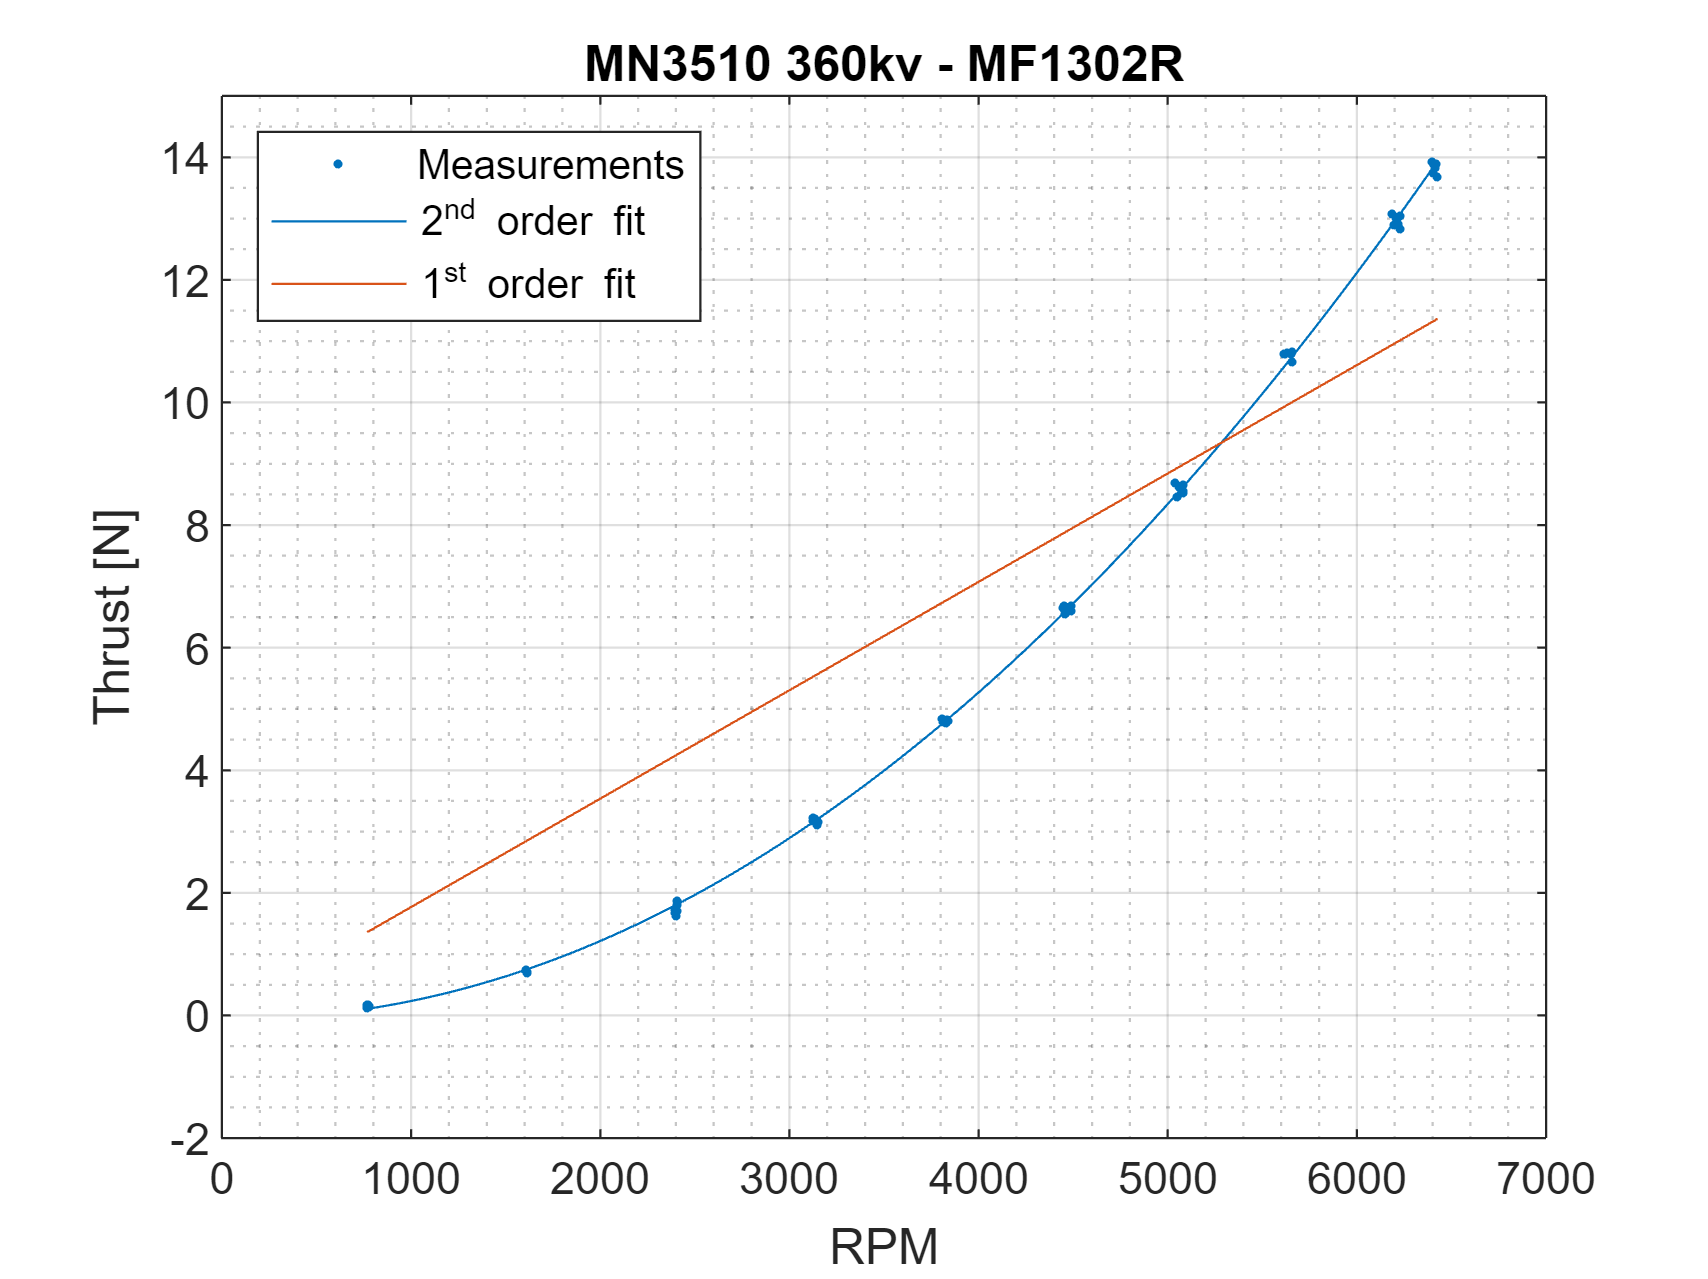

figure(1)
clf
plot(rpm,T,'.','color',[0, 0.4470, 0.7410])
hold on
plot(rpm1,T_f,'color',[0, 0.4470, 0.7410])
plot(rpm1,T_f_lin,'color',[0.8500, 0.3250, 0.0980])
ylim([-2,15])
xlabel('RPM')
ylabel('Thrust [N]')
grid on
grid minor
legend("Measurements","2^{nd} order fit","1^{st} order fit",'Location','northwest')
title('MN3510 360kv - MF1302R')

width = 3;     % Width in inches
height = 3;    % Height in inches
set(gcf,'InvertHardcopy','on');
set(gcf,'PaperUnits', 'inches');
papersize = get(gcf, 'PaperSize');
left = (papersize(1)- width)/2;
bottom = (papersize(2)- height)/2;
myfiguresize = [left, bottom, width, height];
set(gcf,'PaperPosition', myfiguresize);
rmse = rms((T_f_lin-T_f));
max_error = max(abs(T_f_lin-T_f));
%export_fig thrust_curve.pdf

Torque curve vs rpm

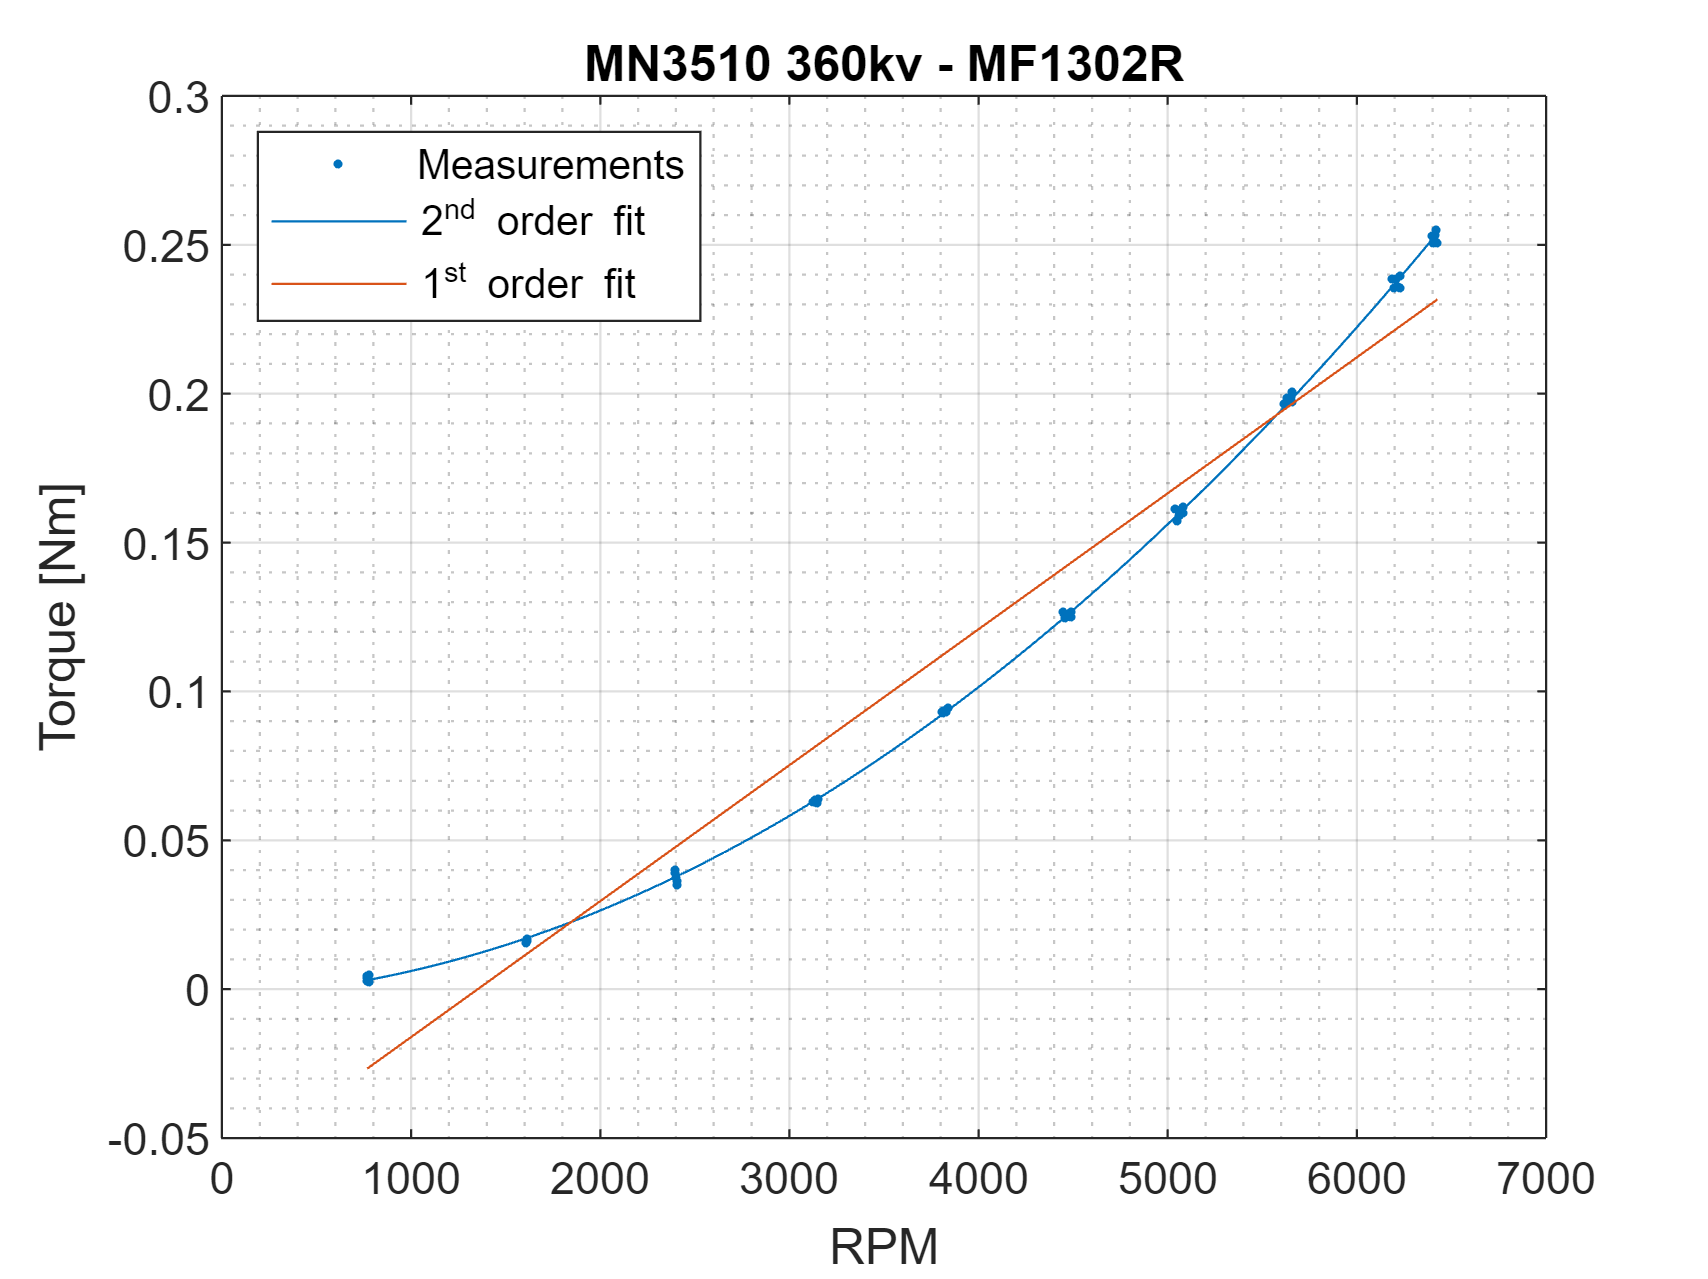

figure(2)
clf
plot(rpm,Qm,'.','color',[0, 0.4470, 0.7410])
hold on
plot(rpm1,Qm_f,'color',[0, 0.4470, 0.7410])
plot(rpm1,Qm_f_lin,'color',[0.8500, 0.3250, 0.0980])
%ylim([0,16.5])
xlabel('RPM')
ylabel('Torque [Nm]')
grid on
grid minor
legend("Measurements","2^{nd} order fit","1^{st} order fit",'Location','northwest')
title('MN3510 360kv - MF1302R')

width = 3;     % Width in inches
height = 3;    % Height in inches
set(gcf,'InvertHardcopy','on');
set(gcf,'PaperUnits', 'inches');
papersize = get(gcf, 'PaperSize');
left = (papersize(1)- width)/2;
bottom = (papersize(2)- height)/2;
myfiguresize = [left, bottom, width, height];
set(gcf,'PaperPosition', myfiguresize);
rmse = rms((Qm_f-Qm_f_lin));
max_error = max(abs((Qm_f-Qm_f_lin)))

max_error = 0.0297

%export_fig torque_curve.pdf

Thrust curve vs pwm

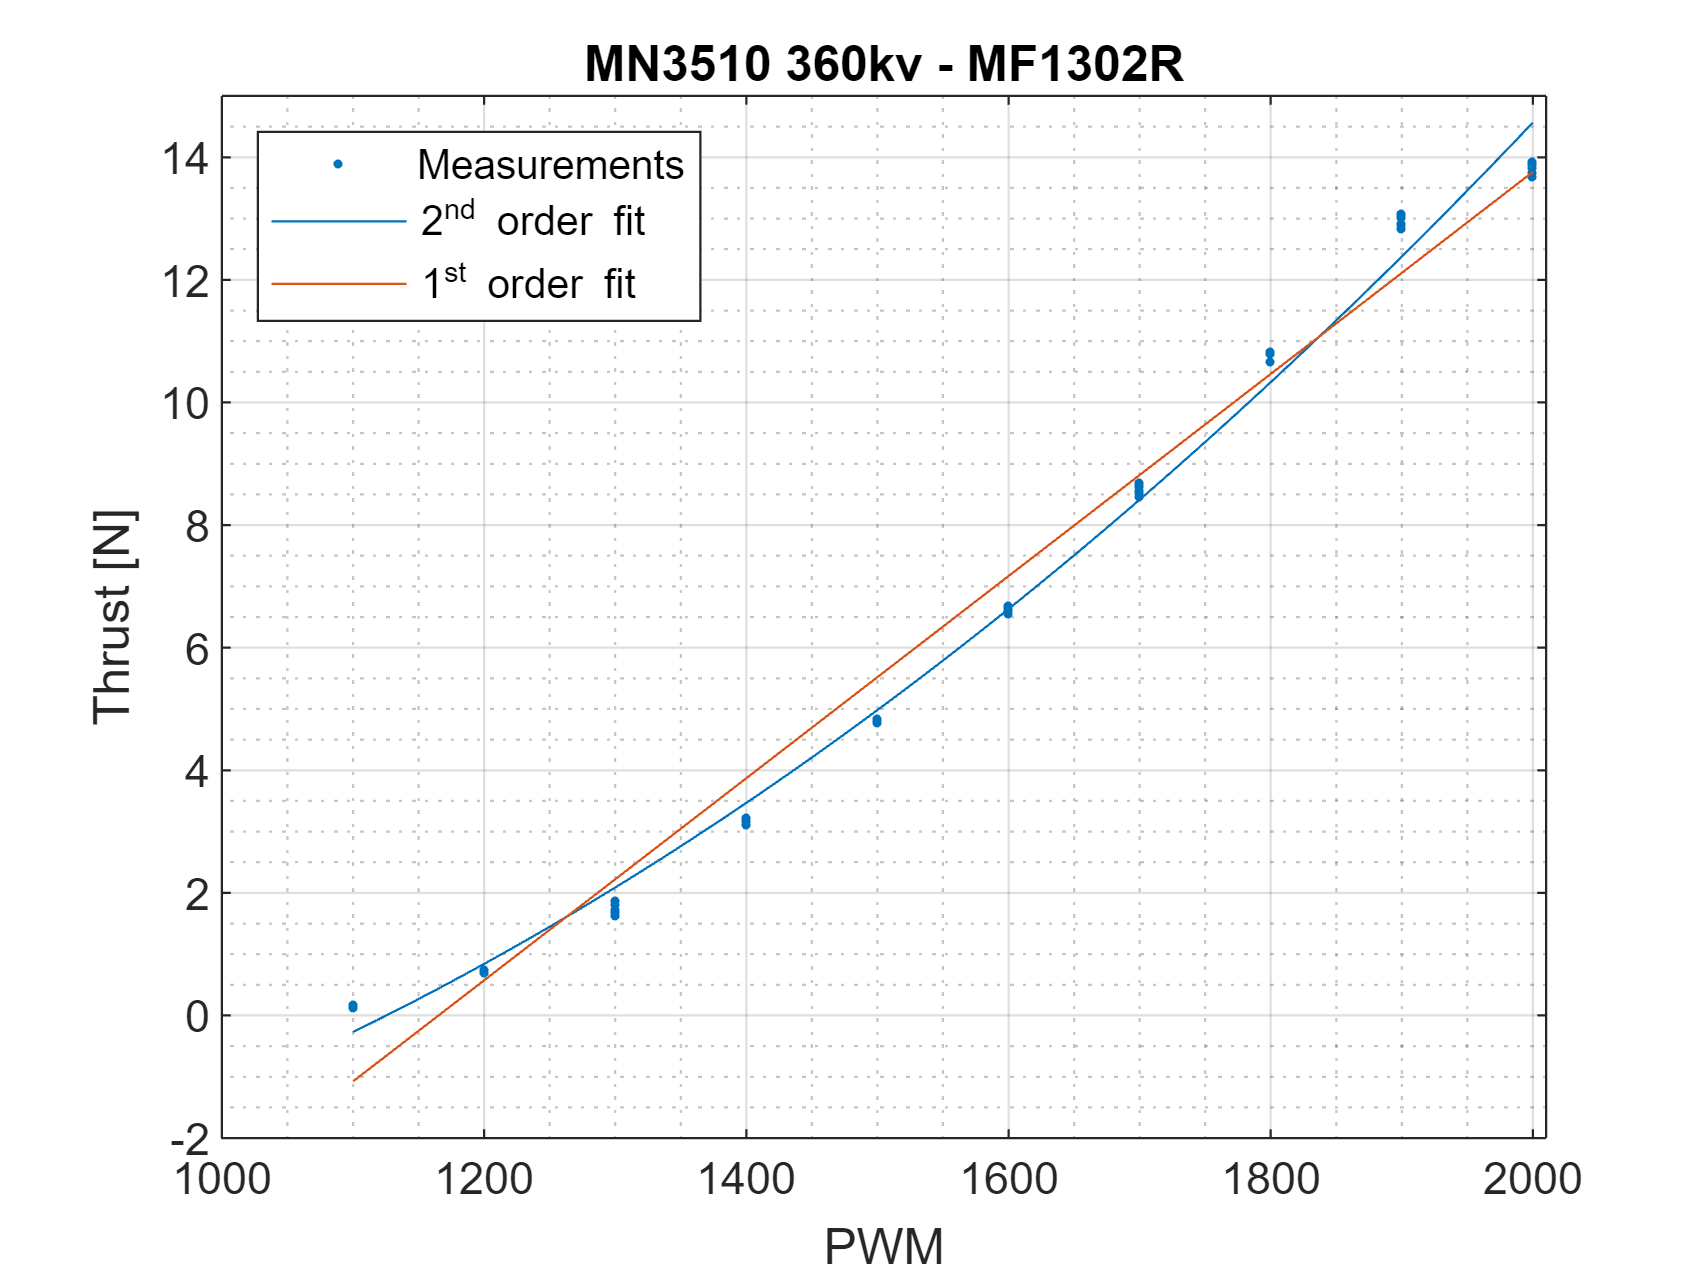

figure(3)
clf
plot(pwm,T,'.','color',[0, 0.4470, 0.7410])
hold on
plot(pwm1,T_f_pwm,'color',[0, 0.4470, 0.7410])
plot(pwm1,T_f_pwm_lin,'color',[0.8500, 0.3250, 0.0980])
ylim([-2,15])
xlim([1000,2010])
xlabel('PWM')
ylabel('Thrust [N]')
grid on
grid minor
legend("Measurements","2^{nd} order fit","1^{st} order fit",'Location','northwest')
title('MN3510 360kv - MF1302R')

width = 3;     % Width in inches
height = 3;    % Height in inches
set(gcf,'InvertHardcopy','on');
set(gcf,'PaperUnits', 'inches');
papersize = get(gcf, 'PaperSize');
left = (papersize(1)- width)/2;
bottom = (papersize(2)- height)/2;
myfiguresize = [left, bottom, width, height];
set(gcf,'PaperPosition', myfiguresize);
rmse = rms((T_f_pwm_lin-T_f_pwm));
max_error = max(abs(T_f_pwm_lin-T_f_pwm));
%export_fig thrust_curve.pdf

Torque curve vs pwm

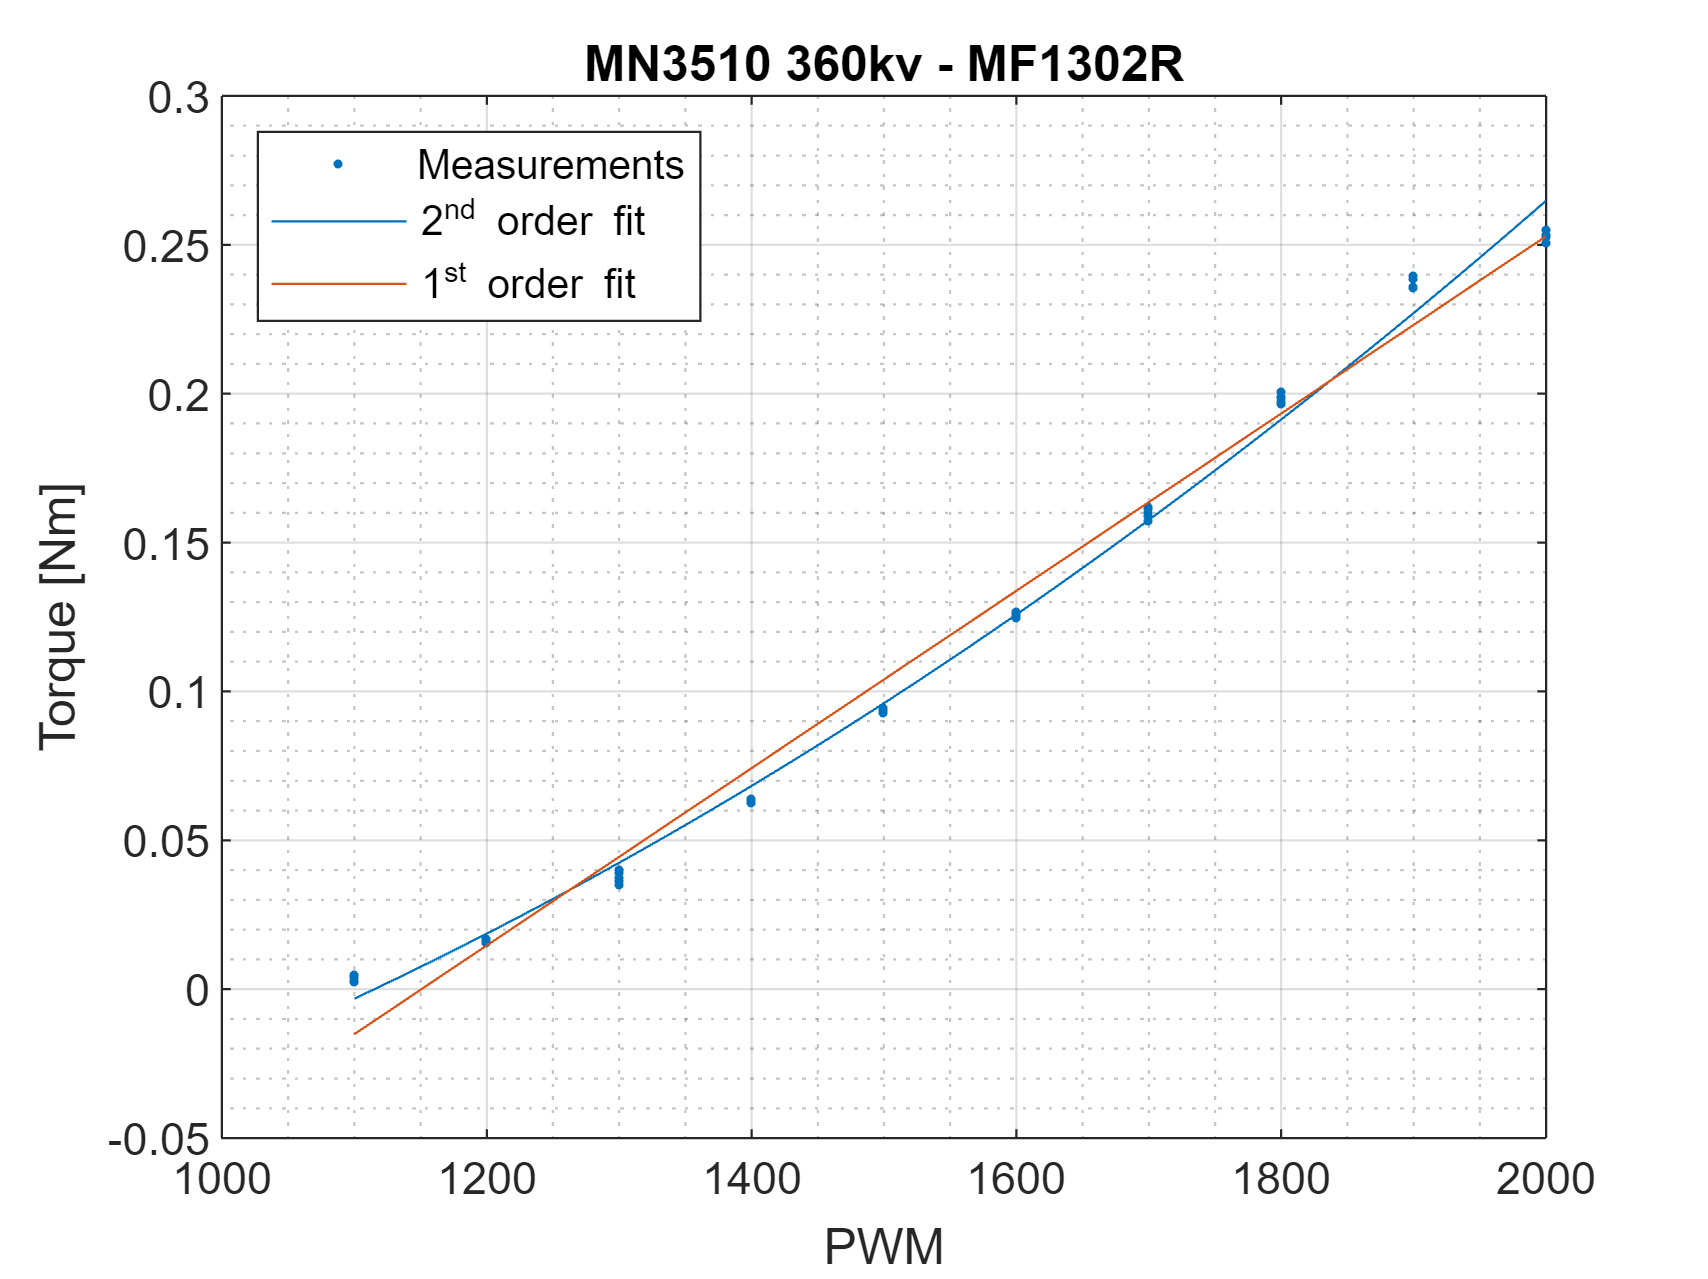

figure(4)
clf
plot(pwm,Qm,'.','color',[0, 0.4470, 0.7410])
hold on
plot(pwm1,Qm_f_pwm,'color',[0, 0.4470, 0.7410])
plot(pwm1,Qm_f_pwm_lin,'color',[0.8500, 0.3250, 0.0980])
%ylim([0,16.5])
xlabel('PWM')
ylabel('Torque [Nm]')
grid on
grid minor
legend("Measurements","2^{nd} order fit","1^{st} order fit",'Location','northwest')
title('MN3510 360kv - MF1302R')

width = 3;     % Width in inches
height = 3;    % Height in inches
set(gcf,'InvertHardcopy','on');
set(gcf,'PaperUnits', 'inches');
papersize = get(gcf, 'PaperSize');
left = (papersize(1)- width)/2;
bottom = (papersize(2)- height)/2;
myfiguresize = [left, bottom, width, height];
set(gcf,'PaperPosition', myfiguresize);
rmse = rms((Q2-Q));

%export_fig torque_curve.pdf
% 

% skew = linspace(0,90);
% f=figure(3);
% t = tiledlayout(1,1);
% clf
% nexttile
% plot(skew,sin(deg2rad(skew)).^3)
% hold on
% plot(skew,cos(deg2rad(skew))-cos(deg2rad(skew)).^3)
% grid on
% grid minor
% xlabel('Skew [deg]')
% ylabel('f(\Lambda) [-]')
% lgd = legend('sin(\Lambda)^3','cos(\Lambda)-cos(\Lambda)^3','NumColumns',2);
% lgd.Layout.Tile = 'north';
% %export_fig trigon.pdf
% exportgraphics(f,'trigon.pdf')
